Edgar Perez Blanco

clear all
format shortG

### Interpolacion inversa

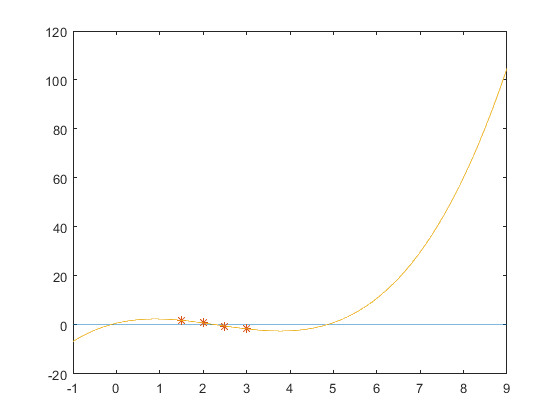

% Datos completos
% x = (0:0.5:3)';
% y = [1.8421 2.4694 2.4921 1.9047 0.8509 -0.4112 -1.5727]';

x = (1.5:0.5:3)';
y = [1.9047 0.8509 -0.4112 -1.5727]';
P = polyfit(x,y,3);

% grafico para comprobar veracidad de la solucion y escoger correctamente
% x0 para utilizar fzero
test_x = linspace(-1,9,500);
plot([-1,9],[0,0],x,y,'*',test_x,polyval(P,test_x),'-');

% Version polyinterp
alpha1 = polyinterp(y,x,0);

% Version con fzero
f = @(t) polyval(P,t);
alpha2 = fzero(f,2);

% Tabla de resultados
Res(1).alpha = alpha1;
Res(1).error_abs = polyval(P,alpha1);
Res(2).alpha = alpha2;
Res(2).error_abs = polyval(P,alpha2);

Res

Res = 1×2 struct array with fields:
    alpha
    error_abs


Segun el polinomio interpolador de grado 3, alpha2 calculada con fzero alpha = 2.3386 se aproxima mas a 0.